# Solving a first order IVP

In this live script, we see how to solve and plot solutions to first order initial value problems (IVPs) of the form


$$\frac{dx}{dt} = f(t,x) \\
x(t_{0}) = x_{0}$$


where $x(t)$ is the unknown function of the independent variable $t$ and $x_{0}$ is the initial value of $x$ at the initial time value $t_{0}$. 

The first thing we can do is to obtain the direction field for the differential equation $\frac{dx}{dt}=f(t,x)$ that is determined by the right hand side function $f(t,x)$.

Consider the example problem where $f(t,x) = t + x$, then we obtain the direction field via the following code. 

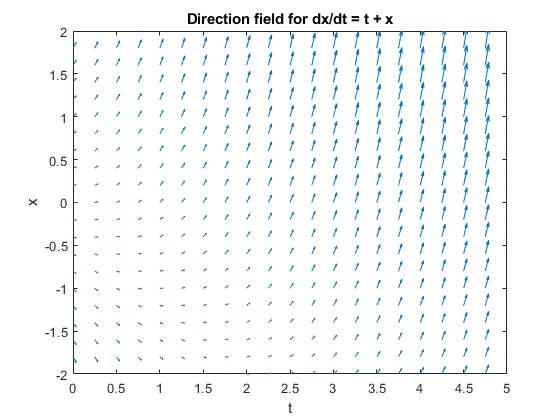

f = @(t,x) t + x;
trange = linspace(0,5,21);
xrange = linspace(-2,2,21);
[T,X] = meshgrid(trange,xrange);
dx = T + X;
dt = ones(size(dx));
quiver(T,X,dt,dx)
xlabel('t')
ylabel('x')
axis([0 5 -2 2])
title('Direction field for dx/dt = t + x')

Now consider $\frac{dx}{dt} = t + x$ with $x(0)=0$ being the given initial condition. Then the solution to the initial condition is the unique curve passing through the point $(0,0)$ that is tangent to the arrows shown in the direction field. Here is the direction field again with the point corresponding to the initial consition shown. 

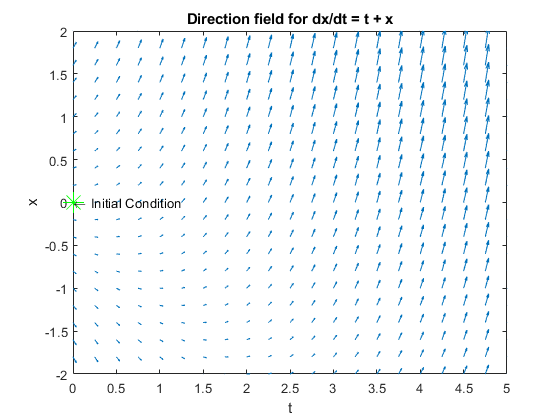

quiver(T,X,dt,dx)
xlabel('t')
ylabel('x')
axis([0 5 -2 2])
title('Direction field for dx/dt = t + x')
hold on
plot(0,0,'g*','MarkerSize',15)
txt1 = ['\leftarrow Initial Condition '];
text(0,0,txt1,'HorizontalAlignment','left')
hold off

Now we will use the MATLAB function ode45 to obtain a numerical solution to the initial value problem


$$\frac{dx}{dt} = t + x \\
x(0) = 0$$


tspan = [0 5]; % time interval over which to solve IVP
x0 = 0; % initial condition
[t, x] = ode45(f,tspan,x0); % call to ode45

The code above computes a numerical solution to the IVP $\frac{dx}{dt} = t + x$ with $x(0)=0$. Now we plot the solution curve together with the direction field and point corresponding to the initial condition. 

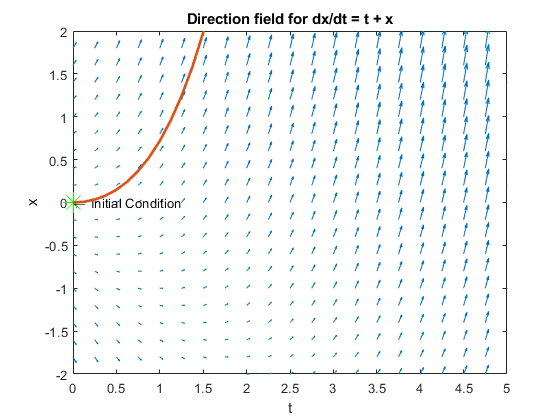

quiver(T,X,dt,dx)
xlabel('t')
ylabel('x')
axis([0 5 -2 2])
title('Direction field for dx/dt = t + x')
hold on
plot(0,0,'g*','MarkerSize',15)
txt1 = ['\leftarrow Initial Condition '];
text(0,0,txt1,'HorizontalAlignment','left')
plot(t,x,'LineWidth',2)
hold off